# Compute Optical Flow Using Lucas-Kanade Algorithm

Read a video file. Specify the timestamp of the frame to be read.

vidReader = VideoReader('visiontraffic.avi','CurrentTime',11);
%vidReader = VideoReader('Mecca.avi','CurrentTime',0);

Create an optical flow object for estimating the optical flow using Lucas-Kanade method. Specify the threshold for noise reduction. The output is an optical flow object specifying the optical flow estimation method and its properties.

opticFlow = opticalFlowLK('NoiseThreshold',0.009);

Create a custom figure window to visualize the optical flow vectors.

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

Read the image frames and convert to grayscale images. Estimate the optical flow from consecutive image frames. Display the current image frame and plot the optical flow vectors as quiver plot.

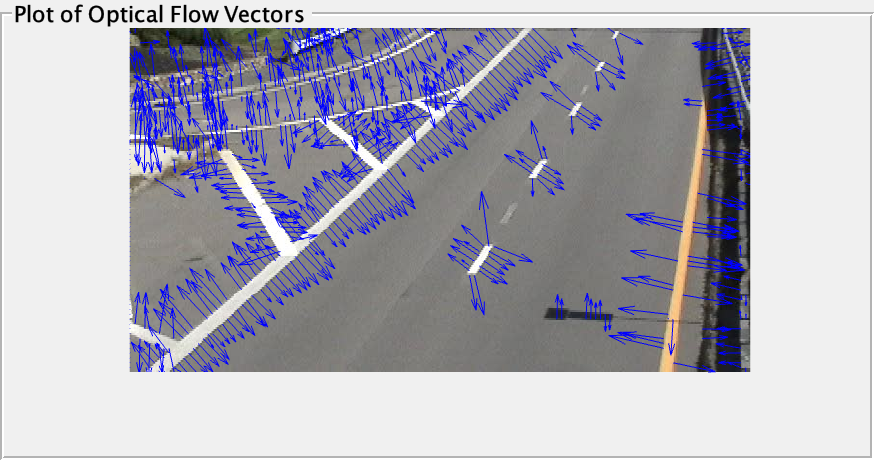

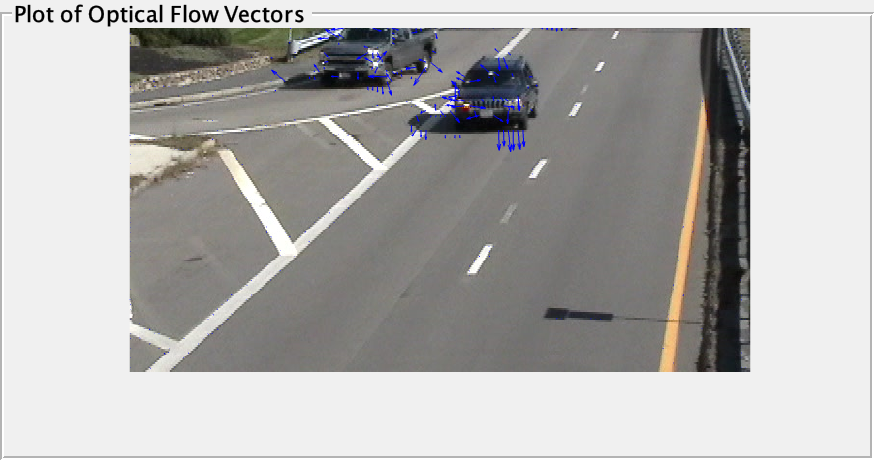

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = rgb2gray(frameRGB);
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
    hold off
    pause(10^-3)
end

*Copyright 2015 The MathWorks, Inc.*